UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

 2024

# Laboratory 4: Bisection Method and False Position

## **Name: Juan Camilo Jaimes Avila**

## **Instructions**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab4_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab4_name_lastname.rar*** and subject **Analisis_Lab4_name** to **jbacquin@uis.edu.co.**

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To apply the bisection method for root-finding.

- To implement the false position method for solving equations numerically.

- To compare theoretical and practical performance of root-finding algorithms.

- To visualize the convergence of numerical methods for root-finding.

- To analyze the effect of stopping criteria on the convergence of iterative methods.

## Guide functions:

You will be introduced to some functions that may be useful for the development of this laboratory. You **DO NOT **have to use them if you do not requier them. This is with the purpose of providing a guide for you to understand Matlab and start coding more eficciently.

**Note:** Remember to save your Matlab functions as '.m' files.

- **Plot:** **plot(X,Y)** Creates a 2D line plot of the data in Y versus the corresponding values in X (it can plot points too). You can change the color or style of lines or add markers by including an optional line specification when calling the plot function. For example:

                ':' represents a dotted line,

                'g:' represents a green dotted line,

                'g:*' represents a green dotted line with star markers,

                '*' represents star markers without a line.

- **hold on:** Hold on sets the axis hold state to on, which preserves the current axis graphs so that new graphs added to the axes do not override existing graphs.

- **hold off:** Hold off sets the hold state of the axes to off so that new graphs added to the axes will clear existing graphs and reset all axis properties.

- **pause(n):** Pause execution for n seconds before continuing. You can use it to plot the points one by one.}

- **figure: **Creates a new figure window using default property values. 

*Source: Matlab documentation.*

**Note:** If you want to learn more about these functions, you can visit [https://la.mathworks.com/help/matlab/](https://la.mathworks.com/help/matlab/)

## Implementing

- **(1 points)** Create a Matlab function called ***my_finding_interval_name_lastname()*** to find two adequate initial points [a, b] given a function f(x) for the bisection method.  Remember that the points need to  satisfy $f(a)f(b)<0.$

%Test your function here.

fun = @(x) x*sin(x)

fun = function_handle with value:
    @(x)x*sin(x)


[a,b]=my_finding_interval_Juan_Jaimes(fun)

a = 3

b = 5

- **(1 points)** Create a Matlab function called ***my_bisection_function_name_lastname(***) to find the root of a function. The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial points [a, b], and the stopping criteria (the number of iterations and the relative error).

%Test your function here. Use the same mathematical function you used above.

Iter=10;
error=1e-5;

%Use the points [a,b] found in the last item.
bisection_root = my_bisection_function_Juan_Jaimes(fun,a,b,Iter,error)

bisection_root = 3.1416

- **(1 points)** Create a Matlab function called ***my_false_position_function_name_lastname()*** to find the root of a function using the false position method. The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial points [a, b], and the stopping criteria (the number of iterations and the relative error).

%Test your function here. Use the same mathematical function you used above.

Iter=100;
error=1e-5;

% Call the false position method function
[falsep_root, IterAfter, errorAfter] = my_false_position_function_Juan_Jaimes(fun, a, b, Iter, error);

% Display results
fprintf('Root: %.6f\nIterations: %d\nRelative Error: %.6f\n', falsep_root, IterAfter, errorAfter);

Root: 3.141593
Iterations: 4
Relative Error: 0.000002


- **(1 points)** Given the function $f\left(x\right)=\left(x-8\right){\left(x-3\right)}^2$ use your scripts to find each one of the roots. Compare the theoretical number of iterations N with respect to the practical number of iterations when the stopping criteria is established as $\epsilon ={1e}^{-2} ,{1e}^{-4} ,{1e}^{-6} ,{1e}^{-8} ,{1e}^{-10}$. Plot the results where the x-label corresponds to the value of epsilon, and the y-label corresponds to the number of iterations for both cases: theoretical and practical. Conclude about the figure.

              Remember that the error formula is: 

## $e =  \frac{ |b - a|}{2^{N+1}}$,

              where **N** is the number of iterations.

%Use your programmed functions and write the code to plot in this section.
fun = @(x) (x-8)*(x-3)^3

fun = function_handle with value:
    @(x)(x-8)*(x-3)^3


[a,b]= my_finding_interval_Juan_Jaimes(fun)

a = 7

b = 9

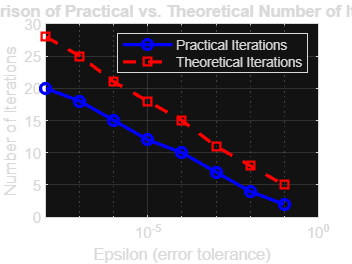


%Initialize variables for plotting
eps_values = logspace(-8, -1, 8);  % Different epsilon values (error tolerances)
practical_iterations = zeros(size(eps_values));
theoretical_iterations = zeros(size(eps_values));

% Set the maximum number of iterations allowed
maxIter = 100;

% Loop through each epsilon value and find the root using the false position method
for i = 1:length(eps_values)
    tol = eps_values(i);  % Current tolerance (epsilon)
    
    % Find the root using the false position method
    [root, Iter, rel_error] = my_false_position_function_Juan_Jaimes(fun, a, b, maxIter, tol);
    
    % Store the practical number of iterations
    practical_iterations(i) = Iter;
    
    % Calculate the theoretical number of iterations
    N_theoretical = log((b - a) / tol) / log(2);
    theoretical_iterations(i) = ceil(N_theoretical);  % Round up to the nearest integer
end

% Plot the results
figure;
semilogx(eps_values, practical_iterations, 'b-o', 'LineWidth', 2, 'DisplayName', 'Practical Iterations');
hold on;
semilogx(eps_values, theoretical_iterations, 'r--s', 'LineWidth', 2, 'DisplayName', 'Theoretical Iterations');
hold off;

% Add labels and title
xlabel('Epsilon (error tolerance)');
ylabel('Number of Iterations');
title('Comparison of Practical vs. Theoretical Number of Iterations');
legend('show');
grid on;

- **(1 points)** Create a Matlab function called ***my_visual_function_name_lastname() ***to visualize the behaviour of both methods (bisection and false posititon). The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial points [a, b], and the number of iterations.

            * Remark: It can be done on the same plot or on separate plots.*

%Test your function here.

fun = @(x) cos(x-1)

fun = function_handle with value:
    @(x)cos(x-1)



[a,b] = my_finding_interval_Juan_Jaimes(fun)

a = 1

b = 3

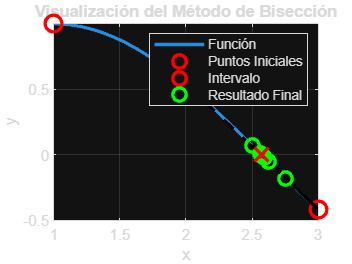

P = 2.5723

Iter= 10;

P=my_visual_bisection_function_Juan_Jaimes(fun,a,b,Iter)